baseGraph5GNR = 'NR_2_6_52'; 
codeRates = [1/4, 1/3, 1/2, 3/5];

[B, Hfull, z] = nrldpc_Hmatrix(baseGraph5GNR);
[mb, nb] = size(B); 
kb = nb - mb; 

EbNodB = 0:0.5:10;  % SNR range (dB)
Nsim = 100;         % Increase for smoother curves
maxItr = 20;        % Max decoding iterations

figure;
hold on;

for i = 1:length(codeRates)
    codeRate = codeRates(i);
    kNumInfoBits = kb * z;
    k_pc = kb - 2;
    nbRM = ceil(k_pc / codeRate) + 2;
    nBlockLength = nbRM * z;

    H = Hfull(:, 1:nBlockLength); 
    nChecksNotPunctured = mb*z - nb*z + nBlockLength;
    H = H(1:nChecksNotPunctured, :); 

    [u, n] = size(H); % u = CNs, n = VNs
    k = n - u;

    % Initialize BER storage
    berVec = zeros(1, length(EbNodB));

    for idx = 1:length(EbNodB)
        jEb = EbNodB(idx);
        EbNo = 10^(jEb/10);
        sigma = sqrt(1 / (2 * codeRate * EbNo));
        succ = 0;

        for NsimIdx = 1:Nsim
            b = randi([0 1], [kNumInfoBits, 1]);
            c = nrldpc_encode(B, z, b');
            c = c(1:nBlockLength)';

            

            s = 1 - 2 * c; % 0 → +1, 1 → -1
            r = s + sigma * randn(nBlockLength, 1);

            decodedBits = SDD(H, r, maxItr);
            decoded = (decodedBits < 0);
            
            decode = decoded(1:kNumInfoBits);
            

            if sum(xor(decode,b)) == 0
                succ = succ + 1;
            end 

        end

        % Store BER for this SNR
        berVec(idx) = (Nsim - succ)/Nsim;
        fprintf('Rate is: %.3f || Eb/No = %0.2f dB || BER = %.6f\n', codeRate, EbNodB(idx), berVec(idx));
    end

    

    % Plot BER curve for this code rate       
    semilogy(EbNodB, berVec, 'LineWidth', 2);
end

Rate is: 0.250 || Eb/No = 0.00 dB || BER = 1.000000


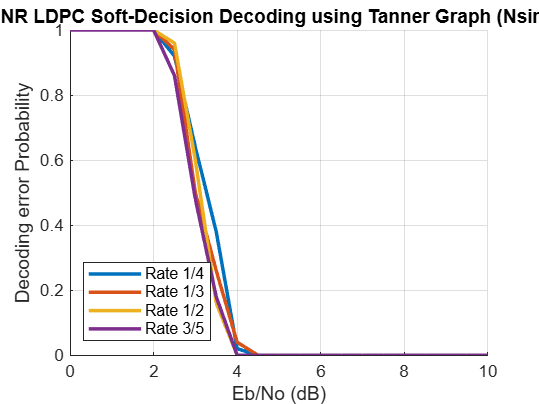


legend('Rate 1/4', 'Rate 1/3', 'Rate 1/2', 'Rate 3/5', 'Location', 'SouthWest');
xlabel('Eb/No (dB)');
ylabel('Decoding error Probability');
title('5G NR LDPC Soft-Decision Decoding using Tanner Graph (Nsim=10)');
grid on;
hold off;


% Helper function: Min-Sum Decoder
function decode = SDD(H, received,maxItr)
    [row,col] = size(H);
    L = zeros(row,col);

    for i=1:row
        for j=1:col
            if H(i,j) ~= 0
                L(i,j) = received(j);
            end
        end
    end
    
    for itr=1:maxItr
        for i=1:row
            min1 = inf;
            min2 = inf;
            countEvenOdd = 0;

            for j=1:col
                if L(i,j) < 0
                countEvenOdd = countEvenOdd + 1;
                end
            end

               tol1=1e-10;
               tol2 = 1e-10;

            for j=1:col
                if L(i,j) ~= 0
                    val = abs(L(i,j));
                    if val < min1 - tol1
                        min2 = min1;
                        min1 = val;
                    elseif(val > min1+tol1) && (val < min2-tol1)
                        min2 = val;
                    end
                end
            end

            p = mod(countEvenOdd,2);

            for j = 1:col
              if L(i,j) ~= 0
                value = abs(L(i,j));
                if abs(value - min1) < tol2
                    if p == 0
                        L(i,j) = sign(L(i,j)) * min2;  % even count: use min2
                    else
                        L(i,j) = -sign(L(i,j)) * min2;  % odd count: use -min2
                    end
                else
                    if p == 0
                        L(i,j) = sign(L(i,j)) * min1;  % even count: use min1
                    else
                        L(i,j) = -sign(L(i,j)) * min1;  % odd count: use -min1
                    end
                end
              end
            end    
        end

        for j=1:col
            sum = 0;
            for i=1:row
                sum = sum + L(i,j);
            end

            sum = sum + received(j);

            for i=1:row
                if L(i,j) ~= 0
                    L(i,j) = sum - L(i,j);
                end
            end

            received(j) = sum;
        end

    end

    decode = received;

end

function [B, H, z] = nrldpc_Hmatrix(BG)
    load(sprintf('%s.txt', BG), BG);
    B = eval(BG);
    [mb, nb] = size(B);
    z = 52;
    H = zeros(mb*z, nb*z);
    Iz = eye(z); I0 = zeros(z);
    for kk = 1:mb
        tmpvecR = (kk-1)*z + (1:z);
        for kk1 = 1:nb
            tmpvecC = (kk1-1)*z + (1:z);
            if B(kk, kk1) == -1
                H(tmpvecR, tmpvecC) = I0;
            else
                H(tmpvecR, tmpvecC) = circshift(Iz, -B(kk, kk1));
            end
        end
    end
end

function cword = nrldpc_encode(B, z, msg)
    [m, n] = size(B);
    cword = zeros(1, n*z);
    cword(1:(n-m)*z) = msg;
    temp = zeros(1, z);

    for i = 1:4
        for j = 1:n-m
            temp = mod(temp + mul_sh(msg((j-1)*z+1:j*z), B(i,j)), 2);
        end
    end

    p1_sh = B(2, n-m+1);
    if p1_sh == -1
        p1_sh = B(3, n-m+1);
    end
    cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp, z - p1_sh);

    for i = 1:3
        temp = zeros(1, z);
        for j = 1:n-m+i
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z), B(i,j)), 2);
        end
        cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
    end

    for i = 5:m
        temp = zeros(1, z);
        for j = 1:n-m+4
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z), B(i,j)), 2);
        end
        cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;
    end
end

function y = mul_sh(x, k)
    if k == -1
        y = zeros(1, length(x));
    else
        y = [x(k+1:end), x(1:k)];
    end
end